# Exploring Inverses & Determinants

## Introduction

Matrices are a very powerful tool in mathematics because they are a convenient and compact way to represent large sets of numbers and with the help of the computer we can easily perfome matrix operations. In particular, we can easily use *Gaussian Elimination* to solve systems of equations of the form $A\underline{x} = \underline{b}$ where 

$A=\left[\begin{array}{c}
a_{11} & a_{12} & \cdots & a_{1n}\\
a_{21} & a_{22} & \cdots & a_{2n}  \\
\vdots & & & \vdots\\
a_{mn}&  a_{m2} & \cdots & a_{mn}
\end{array}\right]$, $\underline{x}=\left[\begin{array}{c}
x_1 \\
x_2   \\
\vdots \\
x_n
\end{array}\right]$ and $\underline{b}=\left[\begin{array}{c}
b_1 \\
b_2   \\
\vdots \\
b_m
\end{array}\right]$.

In this activity we will learn how to calculate inverses and determinants of matrices so we can solve $A\underline{x} = \underline{b}$ for the special case of $n$ equations and $n$ unknonws. That is, when $A$ is a square matrix.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

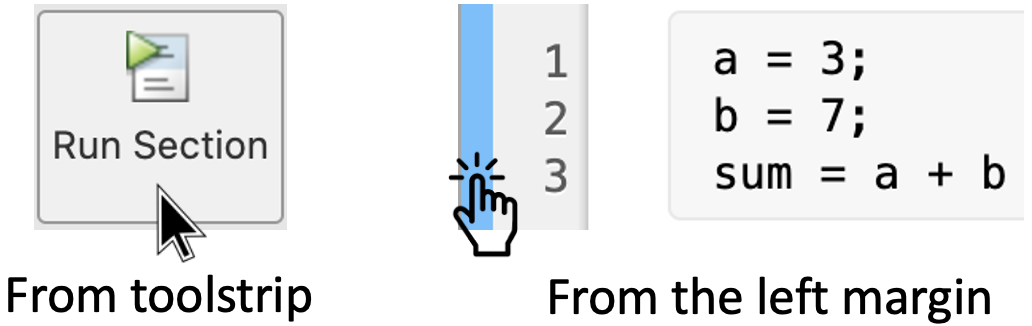

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Inverses & Determinants

Recall that the inverse of a square matrix $A$ is denoted by $A^{-1}$ such that the following relationship holds


$$AA^{-1} = A^{-1}A=I$$


where $I$ is the identity matrix.

In MATLAB we can easily calculate the inverse of a square matrix. For example, consider the 3-by-3 matrix


$$A=\left[\begin{array}{c}
2 & -3 & -1 \\
1 & -2 & -3  \\
-2 & 2 & -5
\end{array}\right]$$


which can be defined as follows:

A = [2, -3, -1; 1, -2, -3; -2, 2, -5];

But before calculating its inverse, we need to check that $A$ is invertible. To do so, we can use the function [`det()`](https://au.mathworks.com/help/matlab/ref/det.html) to find the *determinant* of $A$. Thus we write:

det(A)

Since `det(A)` is not zero, $A$ is invertible and we can proceed to find its inverse by simply writing:

A^(-1)

To confirm that `A^(-1)` is the inverse of `A`, we can just use the *matrix multiplication* defined in MATLAB with the operator `*`. That is:

A * A^(-1)
A^(-1) * A

**Note:** Alternatively, you can write [`inv(A)`](https://au.mathworks.com/help/matlab/ref/inv.html) to calculate the inverse `A`. In this case, we used `A^(-1)` because we are performing matrix multiplication. Otherwise you will get a *warning message* from MATLAB. Try it yourself! Replace `A * A^(-1)` by  `A * inv(A)` in the previous code to see what happens.

### Remark: Matrix operations in MATLAB

It is worth noting that *matrix operations* in MATLAB follow the rules of linear algebra and are not compatible with multidimensional arrays. The required size and shape of the inputs in relation to one another depends on the operation.

For example, if you use the matrix right division operator, `/`, to divide two matrices, the matrices **must have** the same number of columns. But if you use the matrix multiplication operator, `*`, to multiply two matrices, then the matrices **must have** a common *inner dimension*. That is, the number of columns in the first matrix must be equal to the number of rows in the second matrix. For more details see: [Array vs Matrix Operations](https://au.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html).

### 1.1 Symbolic inverses & determinants

In MATLAB we can also calculate the inverse or determinant of symbolic matrices. For example:

syms a b c d
M = [a b; c d];
det(M)
M^(-1)

**Note 1:** Matrix computations involving many symbolic variables can be slow. To increase the computational speed, reduce the number of symbolic variables by substituting the given values for some variables.

### 2. Solving systems of equations: The use of `matrix-left divide`

Consider the system of $n$ equations in $n$ unkowns


$$\begin{array}{rcrcrcrl}
a_{11}x_{1} &+ & a_{12}x_{2} &+ & \cdots &+& a_{1n}x_{n}& =& b_1\\
a_{21}x_{1} &+ &  a_{22}x_{2} &+ & \cdots &+& a_{2n} x_{n} &=& b_2 \\
\vdots & &&&& & & & \vdots\\
a_{nn}x_{1} &+&  a_{n2}x_{2} &+ & \cdots& +& a_{nn}x_{n}& =& b_n
\end{array} $$


which is equivalente to the matrix equation $A\underline{x} = \underline{b}$. In this case, we have a $n\times n$ matrix $A$. If $A$ is invertible, we can solve this system by multiplication on the left by $A^{-1}$ to give

$A^{-1}A\underline{x}=A^{-1}\underline{b}$.

This implies a unique solution $\underline{x}=A^{-1}\underline{b}$.

This method can be easily implemented in MATLAB by using an operator called [`mldivide`](https://au.mathworks.com/help/matlab/ref/mldivide.html), or the backslash operator `\`. If $A$ is not invertible, then we need to use *Gaussian Elimination*.

For example, consider the following system


$$\begin{array}{rc}
2x + y - z &=& 1\\
x + y - 2z &=& - 1 \\
2y - z &=& 3
\end{array}$$


This is equivalent to solving the matrix equation $A\underline{x} = \underline{b}$ where

$A= \left[ 
\begin{array}{ccc}
2 &1 &-1\\
1& 1 & -2\\
0 & 2 &-1
\end{array}
\right] $, $\underline{x}= \left[ 
\begin{array}{c}
x\\
y\\
z
\end{array}
\right] $ and $\underline{b}= \left[ 
\begin{array}{c}
1 \\
-1\\
3 
\end{array}
\right] $.

First, we must initialise the matrices:

A = [2 1 -1; 1 1 -2; 0 2 -1];
b = [1; -1; 3];

Now we simply use the [`mldivide`](https://au.mathworks.com/help/matlab/ref/mldivide.html) operator as follows:

x = mldivide(A,b)  % You can also write A\b, which is shorter

Confirm this result in your notebook.

## 3. Hands on practice

Let's practice what we just learned.

### Activity 1:

The following code generates random 5-by-5 matrices with integer entries:

A = round(10 * rand(5))
B = round(20 - rand(5)) - 10

Compute each of the pairs of numbers that follow:

- $\text{det}(A)$, $\text{det}\left(A^T\right)$

- $\text{det}(A+B)$, $\text{det}(A)+ \text{det}(B)$

- $\text{det}(AB)$, $\text{det}(A)\text{det}(B)$

- $\text{det}\left(A^T B^T\right)$, $\text{det}(A^T)\text{det}(B^T)$

- $\text{det}(A^{-1})$, $1/\text{det}(A)$

- $\text{det}(AB^{-1})$, $\text{det}(A)/\text{det}(B)$ 

In each case, check whether the first number is equal to the second.

**Note:** You can write `A'` or [`transpose(A)`](https://au.mathworks.com/help/matlab/ref/transpose.html) for the transpose $A^T$.

Write your code here:

%{---part 1---}%


%{---part 2---}%


%{---part 3---}%


%{---part 4---}%


%{---part 5---}%


%{---part 6---}%



**Note 2:** If `A` or `B` are singular, i.e. not invertible, then you might get a warning message. If so, just re-run the code until they are non-singular.

### Activity 2:

Calculate the inverse of the matrix


$$C = \left[\begin{array}{c}
1 & 2 & 8 & -2 \\
-2 & -3 & -13 & 3  \\
2 & 2 & 11 & -4 \\
-3 & -4 & -14 & -3
\end{array}\right]$$


**Hint:** Don't forget to check first that the determinant is different to zero.

Write your code here:

If the matrix is invertible, confirm your result by using matrix multiplication. Write your code here:

### Activity 3:

For each matrix $A$ and vector $\underline{b}$ below, use the operator [`mldivide`](https://au.mathworks.com/help/matlab/ref/mldivide.html), or the backslash operator `\`, to solve the system $A\underline{x} = \underline{b}$. 

- $A = \left[\begin{array}{ccc}
1 & 2 & -1 \\
2 & 5 & 1  \\
4 & 6 & -9   
\end{array}\right]$,  $\underline{b} = \left[\begin{array}{r}
-2  \\
1   \\
-16  
\end{array}\right]$

- $A = \left[\begin{array}{rrrr}
1 & 2 & 0 & 1\\
3 & 7 & -2  & 3\\
4 & 6 & 4  & 4\\
 2  &  9  &  -10  & 2
\end{array}\right]$,  $\underline{b} = \left[\begin{array}{r}
0 \\
1   \\
-2 \\
5 
\end{array}\right]$

- $A = \left[\begin{array}{rrrr}
1 & 2 & -1 & 2\\
-2 & -3 & 4  & -2\\
4 & 5 & -9  & 5\\
5  &  13  &  -5  & -1
\end{array}\right]$,  $\underline{b} = \left[\begin{array}{r}
4 \\
0   \\
-1 \\
4
\end{array}\right]$

If it is not possible to solve the system, add a comment mentioning why.

**Hint: **Don't forget to use different variable name to identify each part. 

Write your code here:

%{---part 1---}%


%{---part 2---}%


%{---part 3---}%
